# 程式說明

實例 4.1-1 功能：對含有0~9數字的二值圖像（像素為28×28）進行分類，並計算分類準確率 作者：zhaoxch_mail@sina.com 時間：2020年2月22日 版本：DLTEX1-V1 注：1）本實例主要用於說明如何構建網絡？如何改變網絡結構及網絡結構改變後的影響。所以，請重點關注步驟3 2）做一些網絡結構的調整主要改變步驟3中的相關參數設置即可 3）讀者可以結合註釋（%之後的語句）對程式進行理解

在本例中如何改變網絡的結構? 1)去掉批量歸一化層看效果：分別在第一個 batchNormalizationLayer（第41行）、分別在第二個 batchNormalizationLayer（第46行）所對應的語句之前加%，將其註釋掉 2) 去掉一個卷積層看效果：分別在第卷積層2（第45行）、批量歸一化層2（第46行）、非線性激活函數2（第47行）、池化層2（第48行）所對應的語句之前加%，將其註釋掉 3) 去掉一個卷積層之後，減少卷積核的數量看效果：在2）的基礎上，將卷積層1的卷積核的個數改為4（將40行，函數中第2個參數8改為4）。

## 清除内存、清除螢幕

clear
clc

## 步驟1：加載圖像樣本數據，並顯示其中的部分圖像

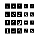

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

## 步驟2：將加載的圖像樣本分為訓練集和測試集（註：在本例中，訓練集的數量為750幅，剩餘的為測試集）

numTrainFiles = 750;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

## 步驟3：構建卷積網絡（註：可以在該部分進行相關參數的設置改進）

layers = [
    imageInputLayer([28 28 1])                    % 输入层，1个通道，像素为28×28
    
    convolution2dLayer([3 3],8,'Padding','same')  % 卷积层1：卷积核大小为3×3，卷积核的个数为8（每个卷积核的通道数与输入图像的通道数相等，本层中每个卷积核1个通道）卷积的方式采用零填充方式（即设定为same方式）
    batchNormalizationLayer                       % 批量归一化层1
    reluLayer                                     % ReLu非线性激活函数1
    maxPooling2dLayer(2,'Stride',2)               % 池化层1：池化方式：最大池化；池化区域为2×2，步长为2
    
    convolution2dLayer([3 3],16,'Padding','same') % 卷积层2：卷积核大小为3×3，卷积核的个数为16（每个卷积核的通道数与输入特征图的通道数相等，本层中每个卷积核8个通道）卷积的方式采用零填充方式（即设定为same方式）
    batchNormalizationLayer                       % 批量归一化层2
    reluLayer                                     % ReLu非线性激活函数2
    maxPooling2dLayer(2,'Stride',2)               % 池化层2：池化方式：最大池化；池化区域为2×2，步长为2
    
    fullyConnectedLayer(10)                       % 全连接层：将全连接层输出的个数设置为10个
    softmaxLayer                                  % softmaxLayer层：输出每个输出的概率
    classificationLayer ];                        % 分类层：根据上一层的输入的概率，进行分类并输出


analyzeNetwork(layers)

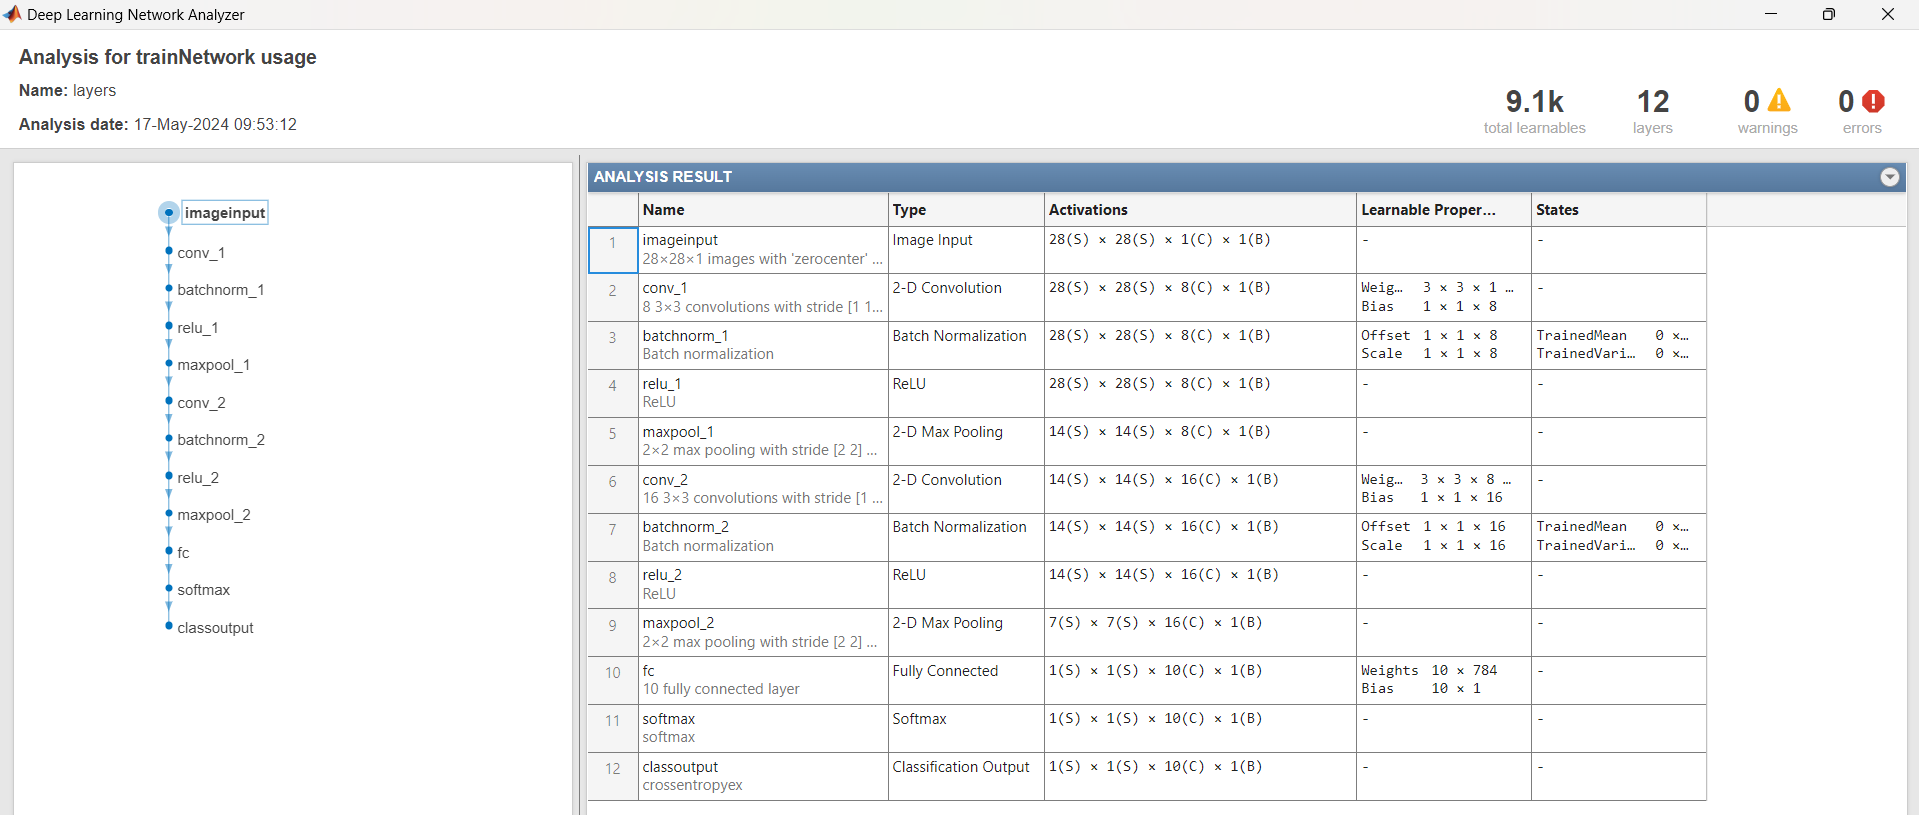

## 步驟4：配置訓練選項並開始訓練

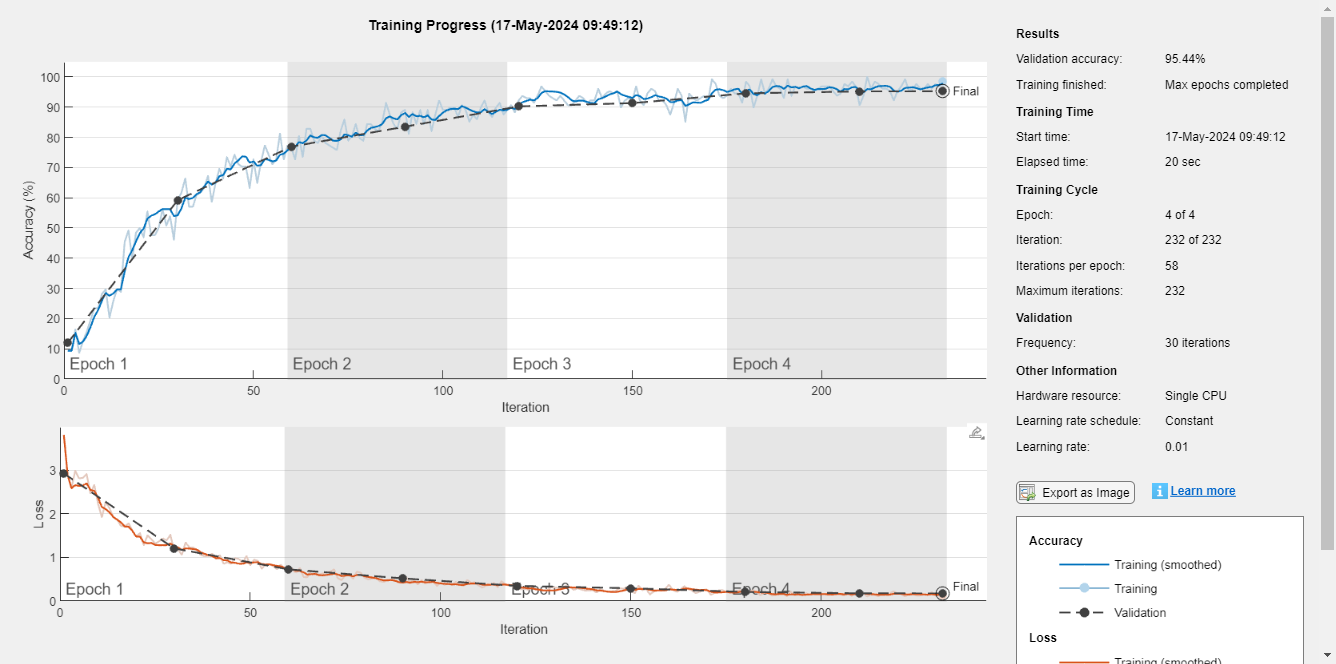

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');                

% 配置训练选项
%'sgdm'表示使用具有动量的随机梯度下降方法来训练网络；'InitialLearnRate'设置初始学习率为0.01；'MaxEpochs'将最大训练轮数设置为4；'Shuffle'表示打乱数据，'every-epoch'则代表每一轮训练都打乱一次数据；'ValidationData'用于设置验证数据集，'ValidationFrequency'设置验证频率为30；'Verbose'设置为false则不显示进度信息；'Plots'打开训练进度图。

net = trainNetwork(imdsTrain,layers,options); %对网络进行训练

## 步驟5：將訓練好的網絡用於對新的輸入圖像進行分類，並計算準確率

YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.9544